# **Matlab案例代码解析**

## 4. 图像信号处理案例

### 4.2 图像分割

#### **4.2.1 大津法（Otsu） **

#### **4.2.2 最大熵**

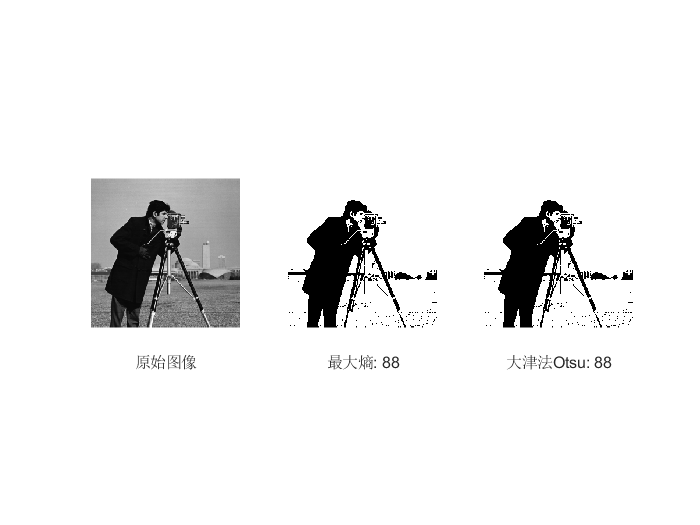

clear; clc;
I = imread('cameraman.tif');
subplot(1, 3, 1)
imshow(I);
xlabel('原始图像');
II = double(I);
% 使用最大熵计算阈值
level1 = ThresholdMaxEntropy(II);      
BW = imbinarize(I, level1 / 255);     
subplot(1, 3, 2)
imshow(BW);
xlabel(['最大熵: ', num2str(level1)]);
% 使用大津法计算阈值
level2 = ThresholdOtsu(II);                
BW = imbinarize(I, level2 / 255);
subplot(1, 3, 3)
imshow(BW);
xlabel(['大津法Otsu: ', num2str(level2)]);